# ECE 203 Lab Assignment 3: Multi-Path Interferance

### ### Agam Goyal ###

# Live Script containing skeleton code for Lab Assignment 3 created by Talha Sultan, 02/2021 #

## Prepare workspace

close all
clear

% Complete the following lines of Code 
% Uncomment to run

dt = 1000; % meters
dxr = 100; % meters
dyr = 900; % meters
c = 3*10^8; % speed of radio signal propagation meters/sec.

## Part (a): Direct path propagation delay t1 from vehicle to Transmitter

% Complete the following lines of Code 
% Write dir_delay function and then uncomment to call function

xv1 = 0;
xv2 = 65;
t1_1 = dir_delay(xv1, dt, c);
t1_2 = dir_delay(xv2, dt, c);

disp('Part (a) Direct Path Delay')

Part (a) Direct Path Delay


disp(['t1(0) = ' num2str(dir_delay(xv1,dt,c)) ' sec'])

t1(0) = 3.3333e-06 sec


disp(['t1(65) = ' num2str(dir_delay(xv2,dt,c)) ' sec'])

t1(65) = 3.3404e-06 sec


## Part (b): Reflective path delay where reflector is at (dxr, dyr)

% Complete the following lines of Code 
% Write dir_delay function and then uncomment to call function
xv = 65

xv = 65

refl_delay(xv,dt,c,dxr,dyr)

ans = 3.4737e-06

% Uncomment to run and check function output for xv = 0
disp('Part (b) Reflective Path Delay')

Part (b) Reflective Path Delay


disp(['t2(0) = ' num2str(refl_delay(65,dt,c,dxr,dyr))])

t2(0) = 3.4737e-06


## Part (c): Received Signal at the Vehicle (Sum of 2 Signals) 

% Complete the following lines of Code 
% Uncomment to run

% Part 1: Predict Amplitude and Phase of rv using Phasor Addition Rule

% Amplitude and Phase Shift of Sinusoid 1: Direct Path from t1(xv)
A1 = 1; phi1  = 0;
% Amplitude and Phase Shift of Sinusoid 2: Direct Path from t2(xv)
A2 = 1; phi2  = pi;
% Use Phasor Addition Rule to calculate A, phi for rv (use pen and paper)

% Hint: Check your work using AddPhasors.m function you wrote down
% previously

Amps = [A1 A2]; Phases = [phi1 phi2];
[A,phi] = AddPhasors(Amps, Phases)

A = 1.2246e-16

phi = 1.5708

% Part 2: Plot total signal rv vs t (for fixed xv)

% Enter Inputs
f = 150*10^6;  % Hz
T = 1/f;  % Period (sec)
t = -3*T/2:T/300:3*T/2  % time samples for three cycles, 100 points per cycle

t = 1.0e-08 *

   -1.0000   -0.9978   -0.9956   -0.9933   -0.9911   -0.9889   -0.9867   -0.9844   -0.9822   -0.9800   -0.9778   -0.9756   -0.9733   -0.9711   -0.9689   -0.9667   -0.9644   -0.9622   -0.9600   -0.9578   -0.9556   -0.9533   -0.9511   -0.9489   -0.9467   -0.9444   -0.9422   -0.9400   -0.9378   -0.9356   -0.9333   -0.9311   -0.9289   -0.9267   -0.9244   -0.9222   -0.9200   -0.9178   -0.9156   -0.9133   -0.9111   -0.9089   -0.9067   -0.9044   -0.9022   -0.9000   -0.8978   -0.8956   -0.8933   -0.8911


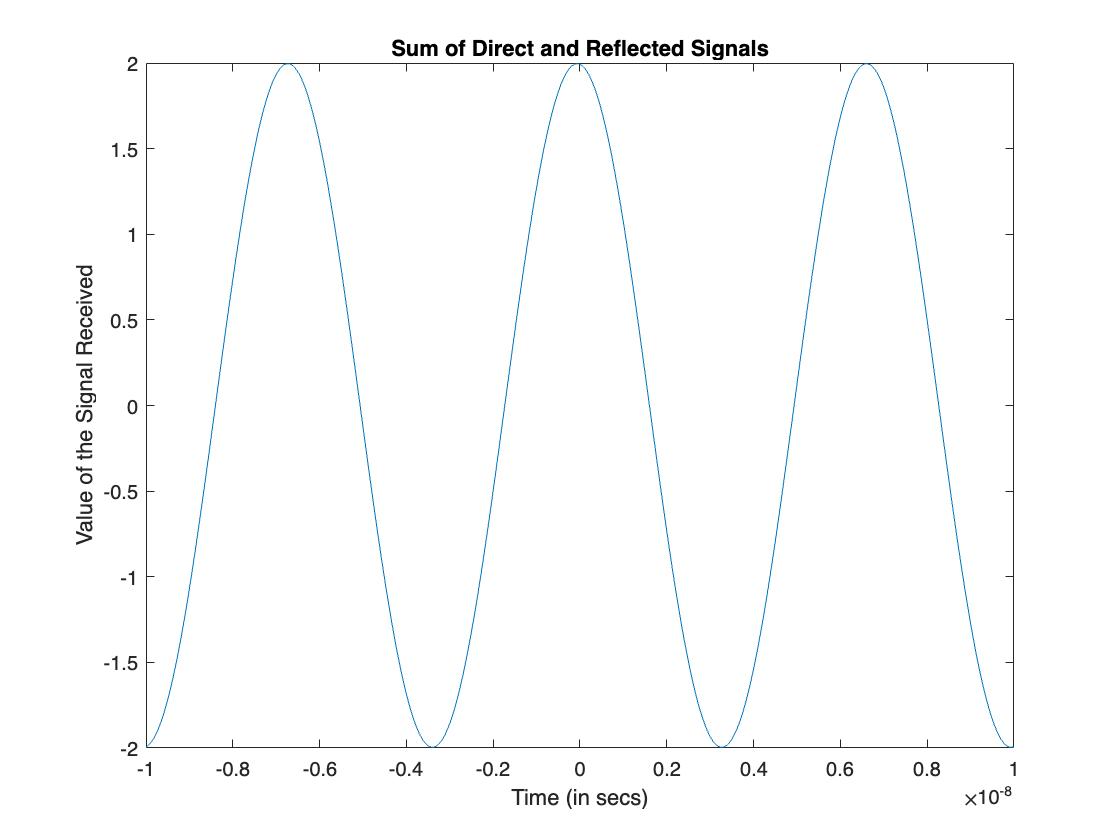

% vehicle position
xv = 0; 

% Call function dir_delay to compute delay of direct path
t1 = dir_delay(xv, dt, c);  

% Generate sinusoid signal from the direct signal
rdir = cos(2*pi*f*(t-t1));

% Call function refl_delay to compute delay of relected path
t2 = refl_delay(xv, dt, c, dxr, dyr); 

% Generate sinusoid signal from the reflected signal
rref = cos(2*pi*f*(t-t2) + pi);

% Compute Sum of Sinusoids 
rv = rdir + rref;

% Plot rv vs t when xv = 0;
figure; 
plot(t, rv)
hold on; 
title('Sum of Direct and Reflected Signals')
xlabel('Time (in secs)')
ylabel('Value of the Signal Received')
hold off

## Part (d) Received signal strength versus xv

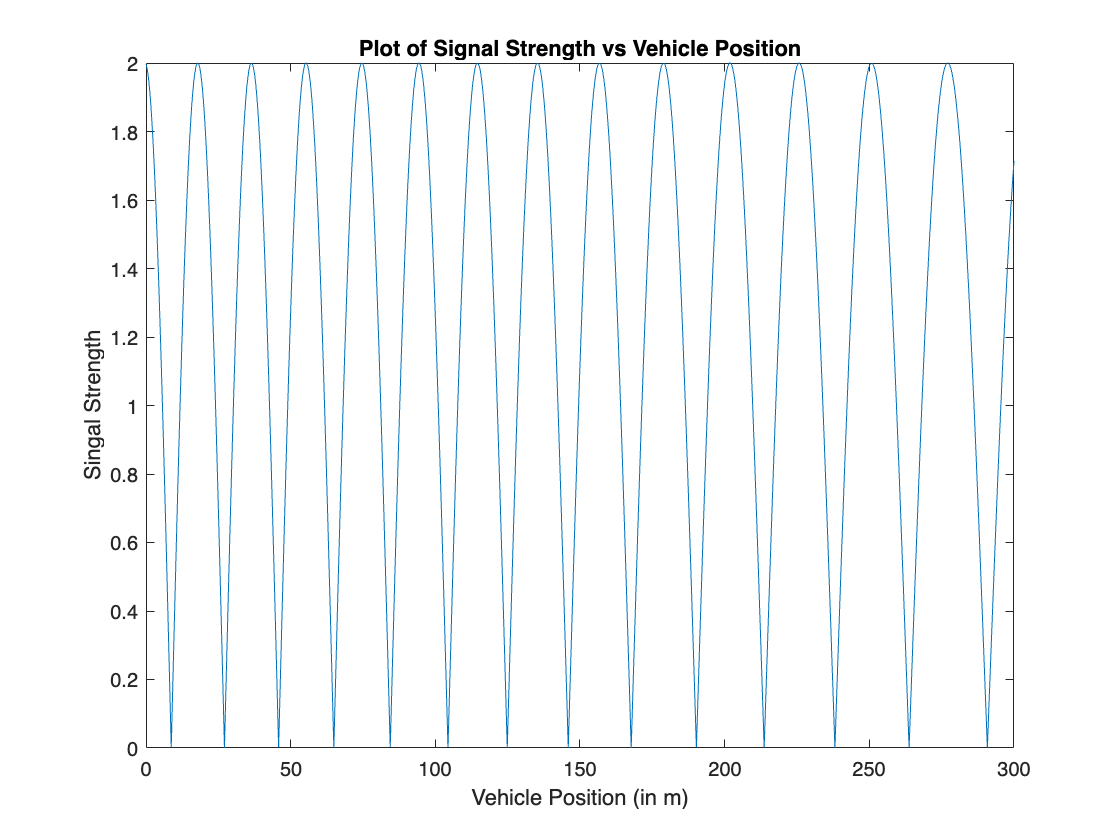

% Complete the following lines of Code 
% Uncomment to run

% Enter Inputs
lambda = c/f; % meters
xv = 0:lambda/100:300; 
N = length(xv); % # of points to use


% Compute Amplitude of rv for different xv
val = zeros(N,1);
for i = 1:N
    cxv = xv(i);
    t1 = dir_delay(cxv, dt, c); 
    t2 = refl_delay(cxv, dt, c, dxr, dyr);

    max = exp(-2*j*pi*f*t1)-exp(-2*j*pi*f*t2);
    val(i) = abs(max);
end

% Plot Amp of rv vs xv
figure,
plot(xv, val);
xlabel('Vehicle Position (in m)');
ylabel('Singal Strength')
title('Plot of Signal Strength vs Vehicle Position')

% Find Minimum Amplitude
round(min(val),4)

ans = 0